## Test different methos for Line of Sight extraction from a tile repository

clear();

Test control

tilepath="D:\fabdem\S23W044_FABDEM_V1-2.tif";
dtedtile="D:\fabdem\S23W044_FABDEM_V1-2.dt0";
tilename="S23W044";
attribution="Copernicus FABDEM 1.2";

lat1 = -23;
lon1 = -44;
lat2 = -22;
lon2 = -43;

Display sample and compute time to load

tic
[Z,R] = readgeoraster(tilepath,"OutputType","double");
toc

Elapsed time is 1.171991 seconds.


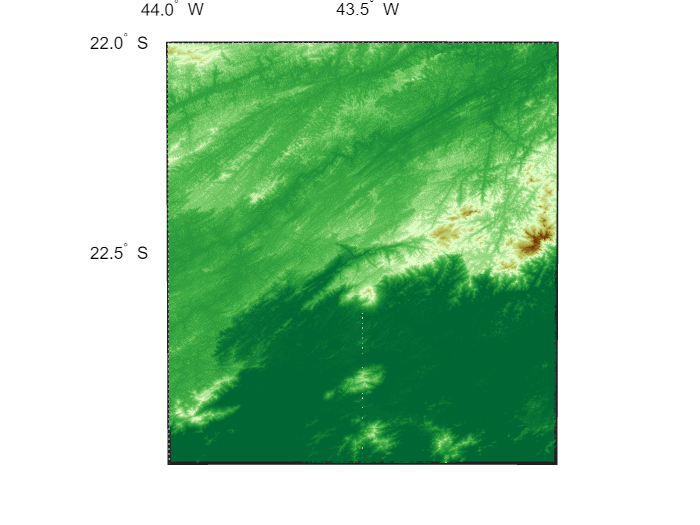

latlim = R.LatitudeLimits;
lonlim = R.LongitudeLimits;
usamap(latlim,lonlim)
geoshow(Z,R,"DisplayType","surface")
demcmap(Z)

Measure the execution time for los2 within the live script

tic
[Z,R] = readgeoraster(tilepath,"OutputType","double");
[vis,visprofile,dist,h,lattrk,lontrk] = los2(Z,R,lat1,lon1,lat2,lon2);
toc

Elapsed time is 0.649514 seconds.


Measure the execution time for los2 within a function

f = @() los_from_tiles(tilepath,lat1,lon1,lat2,lon2)

f = function_handle with value:
    @()los_from_tiles(tilepath,lat1,lon1,lat2,lon2)


timeit(f)

ans = 0.5619

Measure the execution time to add tile to the 

tic
addCustomTerrain(tilename,dtedtile,Attribution=attribution);

Error using addCustomTerrain (line 112)
Array indices must be positive integers or logical values.

toc